# Figure 2E right, S2A

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'A058_data.mat'],'S','settings','allIF');

conditions = settings.conditions

conditions = 20×5 cell array
    {'RO DOX'     }    {[2 3 4]}    {[ 2]}    {[1]}    {[0]}
    {'2i DOX'     }    {[2 3 4]}    {[ 3]}    {[1]}    {[0]}
    {'RO+2i DOX'  }    {[2 3 4]}    {[ 4]}    {[1]}    {[0]}
    {'4/6i DOX'   }    {[2 3 4]}    {[ 5]}    {[1]}    {[0]}
    {'DMSO DOX'   }    {[2 3 4]}    {[ 6]}    {[1]}    {[0]}
    {'RO DMSO'    }    {[2 3 4]}    {[ 7]}    {[1]}    {[0]}
    {'2i DMSO'    }    {[2 3 4]}    {[ 8]}    {[1]}    {[0]}
    {'RO+2i DMSO' }    {[2 3 4]}    {[ 9]}    {[1]}    {[0]}
    {'4/6i DMSO'  }    {[2 3 4]}    {[10]}    {[1]}    {[0]}
    {'DMSO DMSO'  }    {[2 3 4]}    {[11]}    {[1]}    {[0]}
    {'500nM TAK'  }    {[5 6 7]}    {[ 2]}    {[1]}    {[0]}
    {'250nM TAK'  }    {[5 6 7]}    {[ 3]}    {[1]}    {[0]}
    {'125nM TAK'  }    {[5 6 7]}    {[ 4]}    {[1]}    {[0]}
    {'62.5nM TAK' }    {[5 6 7]}    {[ 5]}    {[1]}    {[0]}
    {'31.25nM TAK'}    {[5 6 7]}    {[ 6]}    {[1]}    {[0]}
    {'15.6nM TAK' }    {[5 6 7]}    {[ 7]}    {[1]}    {

framesPerHr = 60/12;
 frameDrugAdded =0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;



times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};
% 
for i = 1:length(S)
    S(i).frameDrugAdded = conditions{i,5};
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = ( S(i).frameDrugAdded - S(i).POI)/framesPerHr;
   S(i).drug_time = S(i).frameDrugAdded/framesPerHr;
end

 drug_time = frameDrugAdded/framesPerHr;

**Gate cells**

xthresh = 6.5e5; %x value of peak
xrange = linspace(1.3e6,1000); %row vector of 1000 points between x and y (all the data)
for i = 1:length(allIF)
    xdata = allIF(i).DNA;
    [f, xi] = ksdensity(xdata,xrange); %probility density plot of values from all xdata to xrange - max x of first peak
    xi_trunc = xi(xi<xthresh); %xi_trunc = all xdata <x thresh (peak of first peak)
    f_trunc = f(xi<xthresh); % f_trunc = probability density estimate for all xdata <x tresh
    [~, maxi] = max(f_trunc); %maxi = index of peak
    N_peak = xi_trunc(maxi); %peak is max of (all xdata<x thresh) which is at index maxi
    S(i).DNA_peak = N_peak;
end


2E right

colors =  [.1 .4 1;.4 .7 0;.5 .8 .2];
f1=figure ('units','inches','position',[0 0 4 4]);
hold on
conds=[20 11];
POI_align = 3;
ally = [];
groups = [];
timeGate = [0 20];
poi_list = [1 3];

 
     poiAligned=poi_list(1);

     for i = 1:length(conds)
       
      ind= ~isnan(S(conds(i)).POI_time(:,poiAligned)) ;
        xdata = S(conds(i)).POI_time(ind,poiAligned);
        ydata = [];
        ydata(:, 1) = ((S(conds(i)).iRFP1(ind) - 1000));
         ydata(:, 2) = 2*(S(conds(i)).dna(ind)/S(conds(i)).DNA_peak);
        ydata(:, 3) = ((S(conds(i)).YFP1(ind)-50));
        ydata(:,4) = ((ydata(:,1)./ydata(:,3)));
     
       if poiAligned==1
               %gated by time of mitosis
              
        ind = xdata > 0 & xdata <12 &ydata(:,4)>=0 & isnan(S(conds(1)).POI(ind,3));
         dapi = ydata(ind,2);
        xdata = xdata(ind);
        ydata = ydata(ind,4);
       
       else 
       
          ind = xdata < 3& xdata > 1 & ydata(:,4) >=0;
           dapi = ydata(ind,2);
        xdata = xdata(ind);
        ydata = ydata(ind,4);
        
       end 
      ally = [ally; ydata];
    groups = [groups; repmat(i,size(ydata))];
    

 sum(ind)

      end

ans = 1662

ans = 899

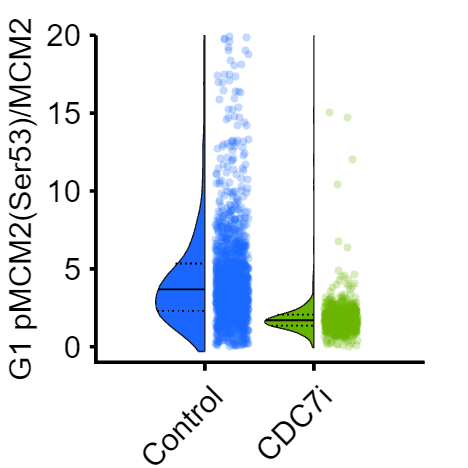

 

cols = repmat({colors(1,:),colors(2,:)}',1,1);
groupcol = repmat([colors([1 2 ],:)],1,1);
figure(f1)
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1.1,'divFactor',.5,'histOri','left','widthDiv',[2 1]);
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',.5)
set(h{1},{'FaceColor'},cols)
 hold on
jit = 0.3*rand(size(groups)) + .1;
 scatter(groups+jit, (ally), 20 ,groupcol(groups,:),'filled','MarkerFaceAlpha',.25);
ylabel([ 'G1 pMCM2(Ser53)/MCM2'])

 xticklabels({'Control','CDC7i'})

 ylim([-1 20])
 xtickangle(45)
set(gca,'fontsize',17)

axis square


 p=mediantest(ally(groups==1),ally(groups==2))

p = 4.2584e-187

figure(f1)
print_pdf(['fig_2Eright.pdf'])

S2A

colors =  [.1 .4 1;.1 .4 .5;.5 .8 .5];

conds=[20];
POI_align = 3;
ally = [];
groups = [];
timeGate = [0 20];

poi_list = [1 3];
 
    

     for i = 1:length(poi_list)
        poiAligned=poi_list(i);
      ind= ~isnan(S(conds(1)).POI_time(:,poiAligned)) ;
        xdata = S(conds(1)).POI_time(ind,poiAligned);
        ydata = [];
        ydata(:, 1) = real(log2((S(conds(1)).iRFP1(ind) - 1000)));
         ydata(:, 2) = 2*(S(conds(1)).dna(ind)/S(conds(1)).DNA_peak);
        ydata(:, 3) = real((log2((S(conds(1)).YFP1(ind)-50))));
        ydata(:,4) = ((ydata(:,1)./ydata(:,3)));
     
       if poiAligned==1
           %fixation 0-4 hours after mitosis
        ind = xdata <=4 & xdata >= 0&  isnan(S(conds(1)).POI(ind,3))& log2(S(conds(1)).RFP2(ind))<=9 ;
 
        xdata = xdata(ind);
        ydata = ydata(ind,3);
       
       elseif poiAligned ==2
          ind = xdata < 2 & xdata >= 0 & isnan(S(conds(1)).POI(ind,3))  ;
    
        xdata = xdata(ind);
        ydata = ydata(ind,3);

         elseif poiAligned ==3
             %fixation 0-2 hours after S phase
          ind = xdata <= 2 & xdata >= 0 &  log2(S(conds(1)).RFP2(ind))>9;
      
        xdata = xdata(ind);
        ydata = ydata(ind,3);
        
        
       end 


              ally = [ally; ydata];
            groups = [groups; repmat(i,size(ydata))];
         
         sum(ind)


      end

ans = 684

ans = 289

 

cols = repmat({colors(1,:),colors(2,:)}',1,1);
groupcol = repmat([colors([1 2 ],:)],1,1);
figure ('units','inches','position',[0 0 4 4])
set(gca,'fontsize',16)
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',.5,'histOri','left','widthDiv',[2 1]);
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',.5)
set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.25);
ylabel([ 'log2[Chromatin-Bound MCM2 (RFU)]'])

p=mediantest(ally(groups==1),ally(groups==2))

p = 0.3023

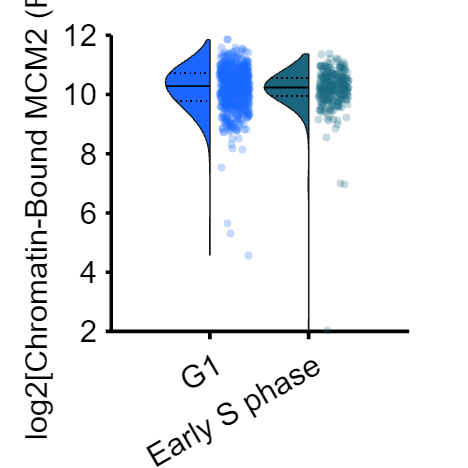




xticklabels({'G1','Early S phase'})
 ylim([2 12])

set(gca,'fontsize',17,'linewidth',2)
axis square

 % print_pdf(['fig_S2A.pdf'])